## **2. Load the data set **

load diabetes_data

## **3. Split the data set**

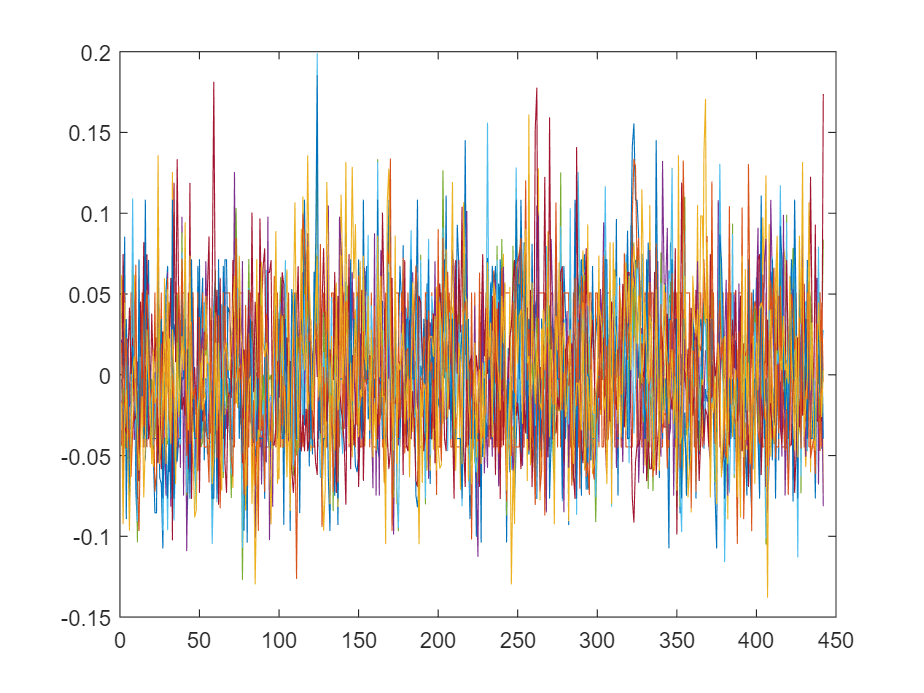

X = diabData(:,1:10);
Y = diabData(:,end);

%X got 442 row and 10 col
plot(X)

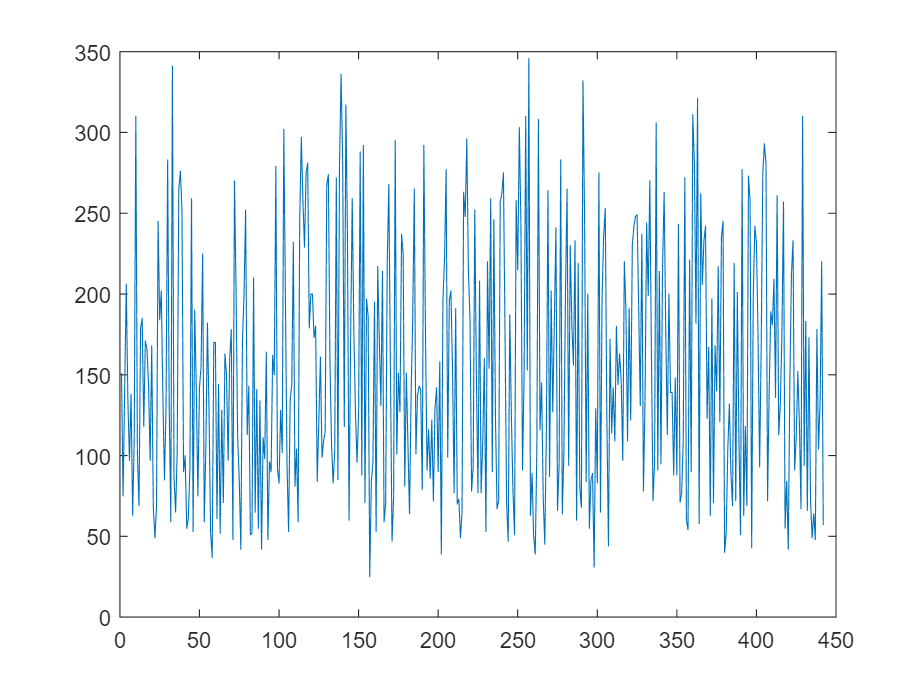

% Y got 442 row and 1 col
plot(Y)

### Randomly split the data into 2 sets training_set 70% and test_set 30%

[m,n] = size(diabData) %to get the m=442

m = 442

n = 11

P = 0.7; %percentage 70%
idx = randperm(m);
num_train = round(P*m);

X_Training = X(idx(1:num_train),:);
Y_Training = Y(idx(1:num_train),:);
X_Testing = X(idx(1:(num_train+1):end),:);
Y_Testing = Y(idx(1:(num_train+1):end),:);


## 4. Linear Regression Model 

%fitting the model using linear regression
mdl_train = fitlm(X_Training, Y_Training)

mdl_train = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10

Estimated Coefficients:
                   Estimate      SE       tStat        pValue   
                   ________    ______    ________    ___________

    (Intercept)     153.27     3.1533      48.605    1.0696e-143
    x1             -57.121     75.896    -0.75263        0.45227
    x2             -192.59     75.462     -2.5521       0.011206
    x3              527.19      80.55      6.5448     2.5972e-10
    x4              312.77     81.072       3.858     0.00014017
    x5             -1359.8     511.43     -2.6588       0.008266
    x6              920.46     414.99       2.218       0.027306
    x7             

plot(mdl_train)
title('Linear Regression Fitting Model 19010054_马那夫')
legend({'Fitted Data','Fit: y=1727.86*x','95% conf.'})

normalEQT = (inv(X_Training'*X_Training))*(X_Training'*Y_Training);
fprintf('%f',normalEQT);

138.020827-82.875716419.011220166.346790-1639.0338961313.451534255.795632-67.4277771272.845225-83.532255

predict = X_Testing*normalEQT;
fprintf('%f', predict);

-86.032020-10.661394

## 4. RMSE Computation

N = m-num_train;
rmse = sqrt(1/N*(sum(Y_Testing - predict).^2))

rmse = 22.6050